# NOTICE

This block of code should already be located somewhere above, either in tasks 1 or 2. This block should be deleted once integrated with the other tasks, but if something breaks in my code, it might be because one of these lines is missing or a variable name is altered.

- Matthew


% Downloads and loads data into the cycleData object
dataFile = matlab.internal.examples.downloadSupportFile("predmaint","batteryagingdata/singlecell/v1/singleCellLifeTimeData.zip");
unzip(dataFile);
load("singleCellLifeTimeData.mat");
cycleData = data(data.Cycle_Index == 1, :);

% Focuses in on data for when battery is charging
chargeData = cycleData(cycleData.Current > 0, :);

t = seconds(chargeData.DateTime - chargeData.DateTime(1));
V = chargeData.Voltage;

# Task 3 - Matlab Calculations

## Preliminary Data

An organization of data that will be used in future calculations.

% Stage 1
s1Time = zeros([1 184]);
for i = 1 : 184
    s1Time(i) = chargeData.Step_Time(i);
end
s1V = zeros([1 184]);
for i = 1 : 184
    s1V(i) = chargeData.Voltage(i);
end
s1I = zeros([1 184]);
for i = 1 : 184
    s1I(i) = chargeData.Current(i);
end

% Stage 2
s2Time = zeros([1 90]);
for i = 1 : 90
    s2Time(i) = chargeData.Step_Time(i + 184);
end
s2V = zeros([1 90]);
for i = 1 : 90
    s2V(i) = chargeData.Voltage(i + 184);
end
s2I = zeros([1 90]);
for i = 1 : 90
    s2I(i) = chargeData.Current(i + 184);
end

% Stage 3
s3Time = zeros([1 165]);
for i = 1 : 165
    s3Time(i) = chargeData.Step_Time(i + 274);
end
s3V = zeros([1 165]);
for i = 1 : 165
    s3V(i) = chargeData.Voltage(i + 274);
end
s3I = zeros([1 165]);
for i = 1 : 165
    s3I(i) = chargeData.Current(i + 274);
end

% Stage 4
s4Time = zeros([1 171]);
for i = 1 : 171
    s4Time(i) = chargeData.Step_Time(i + 439);
end
s4V = zeros([1 171]);
for i = 1 : 171
    s4V(i) = chargeData.Voltage(i + 439);
end
s4I = zeros([1 171]);
for i = 1 : 171
    s4I(i) = chargeData.Current(i + 439);
end

## Energy Loss to Heat (Power)

Power can be used to describe the energy loss due to heat in resistors. Power is $P=I^2 *R$ where I is the current flowing through the battery and R is the battery's internal resistance. The plot Power vs. Time shows us the total power loss over the course of a stage.

Use the drop down box to select a stage.

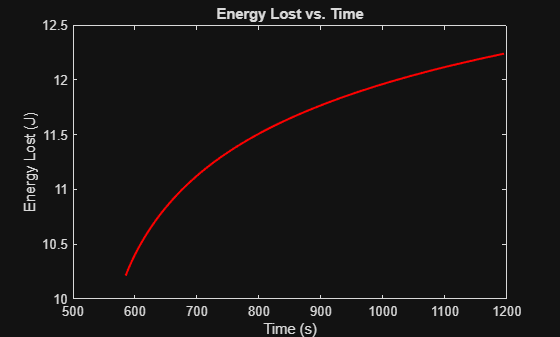

% Internal resistance
R = 0.0173;

% Calculates Power for each Stage
s1P = zeros([1 184]);
s1P(1) = s1I(1) * R;
for i = 2 : 184
    s1P(i) = s1I(i)^2 * R;
end
s2P = zeros([1 90]);
s2P(1) = s2I(1) * R;
for i = 2 : 90
    s2P(i) = s2I(i)^2 * R;
end
s3P = zeros([1 165]);
s3P(1) = s3I(1) * R;
for i = 2 : 165
    s3P(i) = s3I(i)^2 * R;
end
s4P = zeros([1 171]);
s4P(1) = s4I(1)^2 * R;
for i = 2 : 171
    s4P(i) = s4I(i) * R;
end

% Select a Stage
stage = 4;

% Stage 1
if stage == 1
    lostE = zeros([1, 184]);
    lostE(1) = s1P(1) * s1Time(1);
    for i = 2 : 184
        lostE(i) = lostE(i - 1) + (s1P(i) * (s1Time(i) - s1Time(i - 1)));
    end
    figure;
    plot(s1Time, lostE, '-r', 'LineWidth', 1.5);
% Stage 2
elseif stage == 2
    lostE = zeros([1, 90]);
    lostE(1) = s2P(1) * s2Time(1);
    for i = 2 : 90
        lostE(i) = lostE(i - 1) + (s2P(i) * (s2Time(i) - s2Time(i - 1)));
    end
    figure;
    plot(s2Time, lostE, '-r', 'LineWidth', 1.5);
% Stage 3
elseif stage == 3
    lostE = zeros([1, 165]);
    lostE(1) = s3P(1) * s3Time(1);
    for i = 2 : 165
        lostE(i) = lostE(i - 1) + (s3P(i) * (s3Time(i) - s3Time(i - 1)));
    end
    figure;
    plot(s3Time, lostE, '-r', 'LineWidth', 1.5);
% Stage 4
else
    lostE = zeros([1, 171]);
    lostE(1) = s4P(1) * s4Time(1);
    for i = 2 : 171
        lostE(i) = lostE(i - 1) + (s4P(i) * (s4Time(i) - s4Time(i - 1)));
    end
    figure;
    plot(s4Time, lostE, '-r', 'LineWidth', 1.5);
end

% Plots Energy vs. Time
ylabel('Energy Lost (J)');
xlabel("Time (s)");
title('Energy Lost vs. Time');

disp("Total Energy Lost in Stage " + stage + ": " + lostE(end) + "J");

Total Energy Lost in Stage 4: 12.2383J


The first three stages all have a linear relation when comparing energy and time. Current stays nearly constant during these three stages, leading to a constant amount of energy being added to the circuit. 

Stage 4 breaks this trend and instead has an almost natural log like curve. Stage 4 contains data collected from the end of a battery being charged, so as the voltage levels off to 3.6V, current stops flowing through the battery, leading to the amount of energy lost due to internal resistance being zero once current stops.

## Total Energy

Energy can be described as the area under the power curve. We can approximate the area under the power curve by multiplying the power of the battery and the change in time together.

Use the drop down box to select a stage.

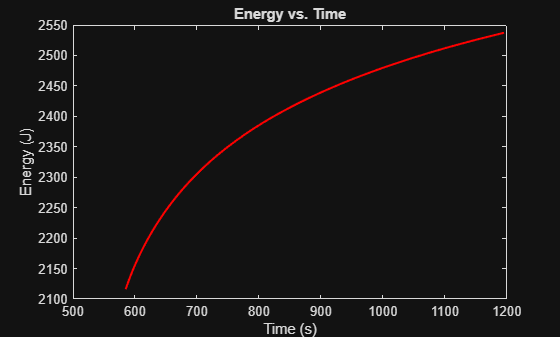

% Calculates Total Power of all Stage
P1 = s1I .* s1V;
P2 = s2I .* s2V;
P3 = s3I .* s3V;
P4 = s4I .* s4V;

% Select a Stage
stage = 4;

% Stage 1
if stage == 1
    E = zeros([1, 184]);
    E(1) = P1(1) * s1Time(1);
    for i = 2 : 184
        E(i) = E(i - 1 ) + (P1(i) * (s1Time(i) - s1Time(i - 1)));
    end
    figure;
    plot(s1Time, E, '-r', 'LineWidth', 1.5);
% Stage 2
elseif stage == 2
    E = zeros([1, 90]);
    E(1) = P2(1) * s2Time(1);
    for i = 2 : 90
        E(i) = E(i - 1 ) + (P2(i) * (s2Time(i) - s2Time(i - 1)));
    end
    figure;
    plot(s2Time, E, '-r', 'LineWidth', 1.5);
% Stage 3
elseif stage == 3
    E = zeros([1, 165]);
    E(1) = P3(1) * s3Time(1);
    for i = 2 : 165
        E(i) = E(i - 1 ) + (P3(i) * (s3Time(i) - s3Time(i - 1)));
    end
    figure;
    plot(s3Time, E, '-r', 'LineWidth', 1.5);
% Stage 4
else
    E = zeros([1, 171]);
    E(1) = P4(1) * s4Time(1);
    for i = 2 : 171
        E(i) = E(i - 1 ) + (P4(i) * (s4Time(i) - s4Time(i - 1)));
    end
    figure;
    plot(s4Time, E, '-r', 'LineWidth', 1.5);
end

% Plots Energy vs. Time
ylabel('Energy (J)');
xlabel("Time (s)");
title('Energy vs. Time');

disp("Total Energy for Stage " + stage + ": " + E(end) + "J");

Total Energy for Stage 4: 2537.255J


Similar to the energy lost due to internal resistivity, the total energy for the first three stages have a linear relation to time. Stage 4 breaks this trend once again because as current stops flowing through the battery, the energy goes down as well.

## Change in Voltage Over Time (dv/dt)

The matlab gradient function estimates the derivative of a set of data by finding the difference between each pair of adjacent data points. We can take this data and plot dv/dt vs. Time to analyze the change in voltage over the change in time.

Use the drop down box to select a stage.

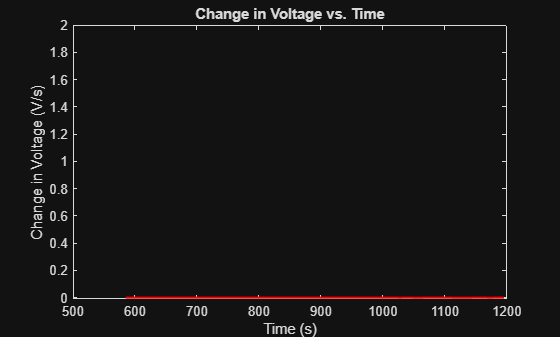

% Select a Stage
stage = 4;

% Calculates dv/dt for each Voltage Value
if stage == 1
    DV = gradient(s1V);
elseif stage == 2
    DV = gradient(s2V);
elseif stage == 3
    DV = gradient(s3V);
else
    DV = gradient(s4V);
end

totalDV =  zeros([1 numel(DV)]);
totalDV(1) = DV(1);
for i = 2 : numel(DV)
    totalDV(i) = totalDV(i - 1) + DV(i);
end

% Plots dv/dt vs t
if stage == 1
    figure;
    plot(s1Time, totalDV, '-r', 'LineWidth', 1.5);
elseif stage == 2
    figure;
    plot(s2Time, totalDV, '-r', 'LineWidth', 1.5);
elseif stage == 3
    figure;
    plot(s3Time, totalDV, '-r', 'LineWidth', 1.5);
else
    figure;
    plot(s4Time, totalDV, '-r', 'LineWidth', 1.5);
end
ylim([-0.01 2]);
% xlim([0 1500])
ylabel('Change in Voltage (V/s)');
xlabel("Time (s)");
 title('Change in Voltage vs. Time');

Stage 1 has a quick jump in the beginning before leveling off, signally the fast charging of a battery in the beginning. Stage 2 and stage 3 have a much lower dv/dt because these stages are past the initial charge, leading to the increase in voltage being much slower. Stage 4 represents the end of the battery being charged, meaning it has reached its limit and so voltage stays at around 3.6V, causing dv/dt to remain around zero.

## V and t at a Specified Percent of Charge

The following code can find the voltage and time values when the battery is at a specific percentage. The time constant tau was estimated by finding the time it takes for the battery to reach 63% charged, which is approximately 1.645s.

Use the slider to change the targeted percentage. 

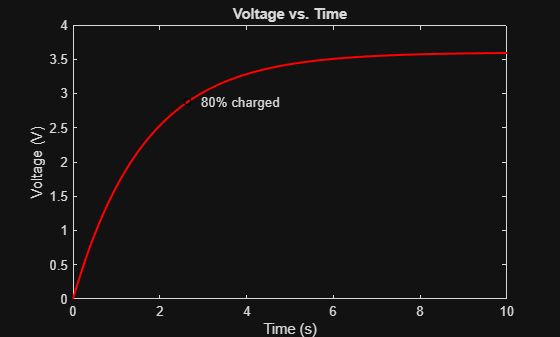

% Time Constant
tau = 1.645;

% Voltage Values
Vs = 3.6000;
Vo = 0;
Vstep = Vs + (Vo - Vs) .* exp(-(1 ./ tau) .* t);

% Desired Percent
percent = 0.8;

% Calculates the Target Voltage and Target Time
Vtarget = Vs * percent;
t_target = 0;
if percent == 1
    for i = 1 : numel(V)
        if abs(Vs - V(i)) <= 0.001
            t_target = t(i);
            break
        end
    end
else
    t_target = -tau * log((Vs * (percent - 1)) / (Vo - Vs));
end

% Plots the Vstep Function
figure;
plot(t, Vstep, '-r', 'LineWidth', 1.5);
ylabel('Voltage (V)');
xlabel("Time (s)");
title('Voltage vs. Time');
hold on;

% X and Y buffer make the text appear more clearly and can
% be manually changed based on the scale of the graph
txtXBuffer = 0.3;
txtYBuffer = 0;
if percent == 1
    txtYBuffer = 0.1;
end

% Marks when the battery reaches the specified charge
txt = "% charged";
plot(t_target, Vtarget, 'ko', 'MarkerSize', 5);

if percent ~= 1
    xlim([0 10]);
end

text(t_target + txtXBuffer, Vtarget + txtYBuffer, (percent * 100) + txt);

disp("Time to reach " + (percent * 100) + "% harged: " + t_target + "s");

Time to reach 80% harged: 2.6475s


disp("Voltage at " + (percent * 100) + "% charged: " + Vtarget + "V");

Voltage at 80% charged: 2.88V


It takes about 2.6 seconds for the battery to reach about 80% charged, but it takes around 1,246 seconds, or nearly 21 minutes, to reach 100% charged. The voltage step equation is $V\left(t\right)=V_s +\left(V_o -V_s \right)e^{\frac{-t}{\tau }}$. Notice as time increases, the exponent of e grows increasingly smaller. As e decreases, the increase in voltage exponentially decreases too, explaining why it only takes 2.6 seconds to reach 80%, but nearly 21 minutes to reach 100%.